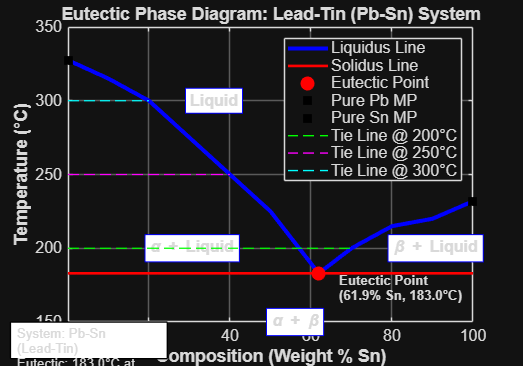

% Eutectic Phase Diagram for Lead-Tin (Pb-Sn) System
% Real data from experimental measurements

clear; clc; close all;

% Composition range (Weight % Sn)
composition = 0:100; % From pure Pb to pure Sn

% Melting points of pure components (in °C)
Tm_Pb = 327.5;    % Melting point of pure Lead
Tm_Sn = 231.9;    % Melting point of pure Tin

% Eutectic point data (experimental values)
eutectic_temp = 183.0;    % Eutectic temperature (°C)
eutectic_comp = 61.9;     % Eutectic composition (% Sn)

% Liquidus line data (experimental points for Pb-Sn system)
% Data from experimental measurements
liquidus_comp = [0, 10, 20, 30, 40, 50, 61.9, 70, 80, 90, 100];
liquidus_temp = [327.5, 315, 300, 275, 250, 225, 183.0, 200, 215, 220, 231.9];

% Solidus line (eutectic horizontal line)
solidus_temp = ones(size(composition)) * eutectic_temp;

% Create the phase diagram
figure('Position', [100, 100, 1000, 700]);

% Plot liquidus line
plot(liquidus_comp, liquidus_temp, 'b-', 'LineWidth', 3, 'DisplayName', 'Liquidus Line');
hold on;

% Plot solidus line (eutectic horizontal)
plot(composition, solidus_temp, 'r-', 'LineWidth', 2, 'DisplayName', 'Solidus Line');

% Plot eutectic point
plot(eutectic_comp, eutectic_temp, 'ro', 'MarkerSize', 10, ...
     'MarkerFaceColor', 'red', 'DisplayName', 'Eutectic Point');

% Plot pure component melting points
plot(0, Tm_Pb, 'ks', 'MarkerSize', 8, 'MarkerFaceColor', 'black', ...
     'DisplayName', 'Pure Pb MP');
plot(100, Tm_Sn, 'ks', 'MarkerSize', 8, 'MarkerFaceColor', 'black', ...
     'DisplayName', 'Pure Sn MP');

% Add phase region labels
text(30, 300, 'Liquid', 'FontSize', 12, 'FontWeight', 'bold', ...
     'BackgroundColor', 'white', 'EdgeColor', 'blue');
text(20, 200, '\alpha + Liquid', 'FontSize', 12, 'FontWeight', 'bold', ...
     'BackgroundColor', 'white', 'EdgeColor', 'blue');
text(80, 200, '\beta + Liquid', 'FontSize', 12, 'FontWeight', 'bold', ...
     'BackgroundColor', 'white', 'EdgeColor', 'blue');
text(50, 150, '\alpha + \beta', 'FontSize', 12, 'FontWeight', 'bold', ...
     'BackgroundColor', 'white', 'EdgeColor', 'blue');

% Label the eutectic point
text(eutectic_comp+5, eutectic_temp-10, ...
     sprintf('Eutectic Point\n(%0.1f%% Sn, %0.1f°C)', ...
     eutectic_comp, eutectic_temp), 'FontSize', 10, 'FontWeight', 'bold');

% Customize the plot
xlabel('Composition (Weight % Sn)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Temperature (°C)', 'FontSize', 14, 'FontWeight', 'bold');
title('Eutectic Phase Diagram: Lead-Tin (Pb-Sn) System', ...
      'FontSize', 16, 'FontWeight', 'bold');

grid on;
legend('Location', 'northeast', 'FontSize', 12);
xlim([0, 100]);
ylim([150, 350]);

set(gca, 'FontSize', 12);
set(gca, 'GridAlpha', 0.3);

% Add some additional features
% Plot tie lines at specific temperatures
tie_temps = [200, 250, 300];
tie_colors = ['g', 'm', 'c'];

for i = 1:length(tie_temps)
    tie_temp = tie_temps(i);
    % Find composition range at this temperature
    comp_range = interp1(liquidus_temp, liquidus_comp, tie_temp);
    if ~isnan(comp_range)
        line([0, comp_range], [tie_temp, tie_temp], ...
             'Color', tie_colors(i), 'LineStyle', '--', 'LineWidth', 1, ...
             'DisplayName', sprintf('Tie Line @ %d°C', tie_temp));
    end
end

% Display system information
annotation('textbox', [0.02, 0.02, 0.3, 0.1], 'String', ...
    {'System: Pb-Sn (Lead-Tin)', ...
     sprintf('Eutectic: %0.1f°C at %0.1f%% Sn', eutectic_temp, eutectic_comp), ...
     'Data Source: Experimental'}, ...
    'FontSize', 10, 'BackgroundColor', 'white', 'EdgeColor', 'black');

hold off;


%% Additional Analysis: Calculate phase fractions at a specific composition
fprintf('\n=== Phase Fraction Analysis ===\n');


=== Phase Fraction Analysis ===


analyze_comp = 40; % Composition to analyze (40% Sn)
fprintf('Analyzing composition: %d%% Sn\n', analyze_comp);

Analyzing composition: 40% Sn



if analyze_comp < eutectic_comp
    % For hypoeutectic composition
    alpha_max = 0; % Pure Pb side
    liquid_comp = analyze_comp;
else
    % For hypereutectic composition
    alpha_max = 100; % Pure Sn side
    liquid_comp = analyze_comp;
end

% Calculate phase fractions at eutectic temperature
if analyze_comp ~= eutectic_comp
    % Using lever rule
    if analyze_comp < eutectic_comp
        % Alpha phase fraction
        alpha_frac = (eutectic_comp - analyze_comp) / eutectic_comp;
        beta_frac = analyze_comp / eutectic_comp;
    else
        % Beta phase fraction
        beta_frac = (analyze_comp - eutectic_comp) / (100 - eutectic_comp);
        alpha_frac = (100 - analyze_comp) / (100 - eutectic_comp);
    end
    fprintf('At eutectic temperature (183°C):\n');
    fprintf('  Alpha phase fraction: %.2f\n', alpha_frac);
    fprintf('  Beta phase fraction: %.2f\n', beta_frac);
end

At eutectic temperature (183°C):


  Alpha phase fraction: 0.35


  Beta phase fraction: 0.65


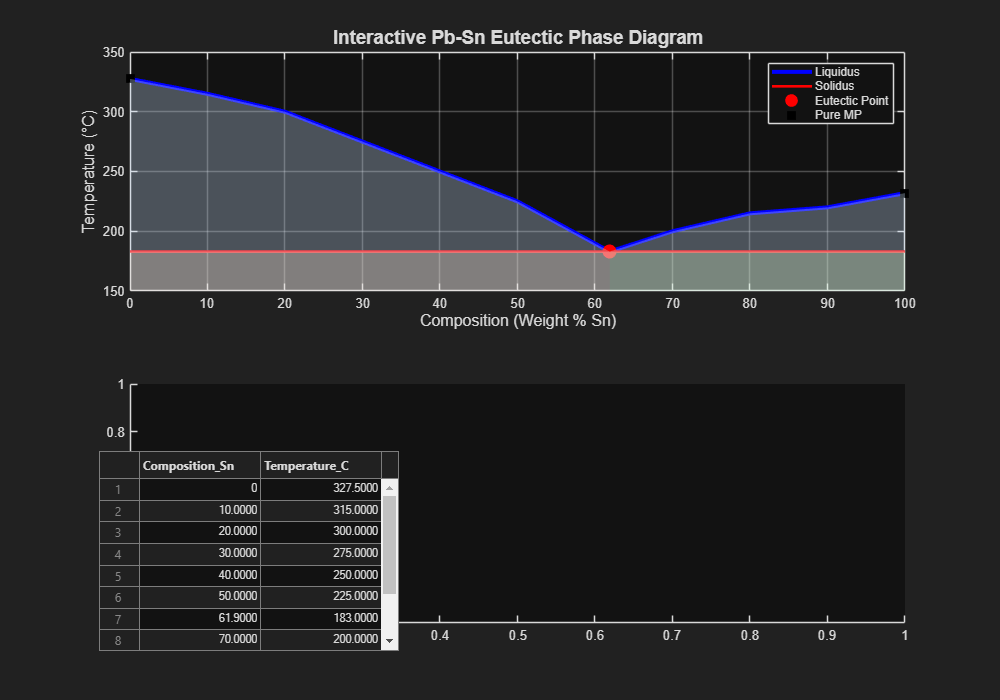


%% Create an interactive version with data cursor
figure('Position', [200, 200, 1000, 700]);

% Main plot
subplot(2,1,1);
plot(liquidus_comp, liquidus_temp, 'b-', 'LineWidth', 3);
hold on;
plot(composition, solidus_temp, 'r-', 'LineWidth', 2);
plot(eutectic_comp, eutectic_temp, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'red');
plot(0, Tm_Pb, 'ks', 'MarkerSize', 8, 'MarkerFaceColor', 'black');
plot(100, Tm_Sn, 'ks', 'MarkerSize', 8, 'MarkerFaceColor', 'black');

% Fill phase regions with light colors
x_fill = [0, liquidus_comp, 100, 100, 0];
y_fill = [350, liquidus_temp, 231.9, 150, 150];
fill(x_fill, y_fill, [0.8, 0.9, 1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

x_fill2 = [0, 0, eutectic_comp, eutectic_comp, 0];
y_fill2 = [150, eutectic_temp, eutectic_temp, 150, 150];
fill(x_fill2, y_fill2, [1, 0.9, 0.8], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

x_fill3 = [eutectic_comp, eutectic_comp, 100, 100, eutectic_comp];
y_fill3 = [150, eutectic_temp, eutectic_temp, 150, 150];
fill(x_fill3, y_fill3, [0.9, 1, 0.8], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

xlabel('Composition (Weight % Sn)', 'FontSize', 12);
ylabel('Temperature (°C)', 'FontSize', 12);
title('Interactive Pb-Sn Eutectic Phase Diagram', 'FontSize', 14);
grid on;
legend({'Liquidus', 'Solidus', 'Eutectic Point', 'Pure MP'}, 'Location', 'northeast');
xlim([0, 100]);
ylim([150, 350]);

% Data table
subplot(2,1,2);
% Create a table of experimental data points
data_table = table(liquidus_comp', liquidus_temp', ...
    'VariableNames', {'Composition_Sn', 'Temperature_C'});
uitable('Data', data_table{:,:}, 'ColumnName', data_table.Properties.VariableNames, ...
    'Position', [100, 50, 300, 200]);


fprintf('\nPhase Diagram created successfully!\n');


Phase Diagram created successfully!


fprintf('Eutectic System: Pb-Sn (Lead-Tin)\n');

Eutectic System: Pb-Sn (Lead-Tin)


fprintf('Eutectic Temperature: %.1f°C\n', eutectic_temp);

Eutectic Temperature: 183.0°C


fprintf('Eutectic Composition: %.1f%% Sn\n', eutectic_comp);

Eutectic Composition: 61.9% Sn
